clc; clear; close all;
% Import functions path
addpath(genpath(strcat(pwd, '\Functions')))
addpath(genpath(strcat(pwd, '\Functions\Globals')))

setPreamble("Default"); setTransform("FFT"); setCoding("CONV");
% Parameters
filename='Test/test_file.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000;
R = 6;
codeRate = 1/2;
modulation_type = 'BPSK';
rep_type = 'Float';

## Test Script

% Transmitter
snr = 11;
% setPreamble("double");
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr);
% Receiver
equalization_method = 'Weiner';
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
output_fileID = fopen('Output/output_test1_BPSK_6_5.txt','w');
fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

## a) Verification that the text file is received correctly for all supported rates

snr = 30;
L = 1000;
setPreamble("Default"); setTransform("FFT"); setCoding("CONV");
% R = 6
[output_data_6, ber_6] = apply_and_save(data, L, 6, 1/2,'BPSK', 'Float', snr, 'Weiner', 'Output/R_6.txt');
% R = 9
[output_data_9, ber_9] = apply_and_save(data, L, 9, 3/4,'BPSK', 'Float', snr, 'Weiner', 'Output/R_9.txt');
% R = 12
[output_data_12, ber_12] = apply_and_save(data, L, 12, 1/2,'QPSK', 'Float', snr, 'Weiner', 'Output/R_12.txt');
% R = 18
[output_data_18, ber_18] = apply_and_save(data, L, 18, 3/4,'QPSK', 'Float', snr, 'Weiner', 'Output/R_18.txt');
% R = 24
[output_data_24, ber_24] = apply_and_save(data, L, 24, 1/2,'16QAM', 'Float', snr, 'Weiner', 'Output/R_24.txt');
% R = 36
[output_data_36, ber_36] = apply_and_save(data, L, 36, 3/4,'16QAM', 'Float', snr, 'Weiner', 'Output/R_36.txt');
% R = 48
[output_data_48, ber_48] = apply_and_save(data, L, 48, 2/3,'64QAM', 'Float', snr, 'Weiner', 'Output/R_48.txt');
% R = 54
[output_data_54, ber_54] = apply_and_save(data, L, 54, 3/4,'64QAM', 'Float', snr, 'Weiner', 'Output/R_54.txt');

fprintf('[Rate 6] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_6), ber_6);

[Rate 6] Tx = 1217104, Rx = 1217104, BER = 0

fprintf('[Rate 9] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_9), ber_9);

[Rate 9] Tx = 1217104, Rx = 1217104, BER = 0

fprintf('[Rate 12] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_12), ber_12);

[Rate 12] Tx = 1217104, Rx = 1217104, BER = 0

fprintf('[Rate 18] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_18), ber_18);

[Rate 18] Tx = 1217104, Rx = 1217104, BER = 0

fprintf('[Rate 24] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_24), ber_24);

[Rate 24] Tx = 1217104, Rx = 1217104, BER = 0

fprintf('[Rate 36] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_36), ber_36);

[Rate 36] Tx = 1217104, Rx = 1217104, BER = 0

fprintf('[Rate 48] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_48), ber_48);

[Rate 48] Tx = 1217104, Rx = 1217104, BER = 4.806491e-04

fprintf('[Rate 54] Tx = %d, Rx = %d, BER = %x', length(data), length(output_data_54), ber_54);

[Rate 54] Tx = 1217104, Rx = 1217104, BER = 1.882337e-03

## b. Comparison between the BER performance of three different preamble lengths.

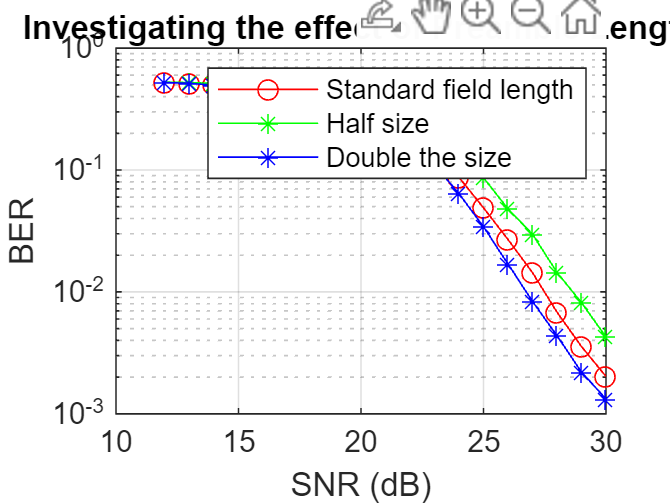

L = 1000;R = 54;codeRate = 3/4;modulation_type = '64QAM';rep_type = 'Float';
equalization_method = 'Weiner';
SNR_DB_Arr = 12:30;
setTransform("FFT"); setCoding("CONV");

setPreamble("Default");
BER_Vals_default_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_default_preamble = [BER_Vals_default_preamble ratio];
end
setPreamble("half");
BER_Vals_half_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_half_preamble = [BER_Vals_half_preamble ratio];
end
setPreamble("double");
BER_Vals_double_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_double_preamble = [BER_Vals_double_preamble ratio];
end
figure();
semilogy(SNR_DB_Arr, BER_Vals_default_preamble,'r-o', ...
    SNR_DB_Arr, BER_Vals_half_preamble,'g-*', ...
    SNR_DB_Arr, BER_Vals_double_preamble, 'b-*');
title('Investigating the effect of Preamble Length');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Standard field length', 'Half size', 'Double the size');

## c. Comparison between the BER performance of the Discrete Cosine Transform (DCT) and Fast Fourier Transform (FFT).

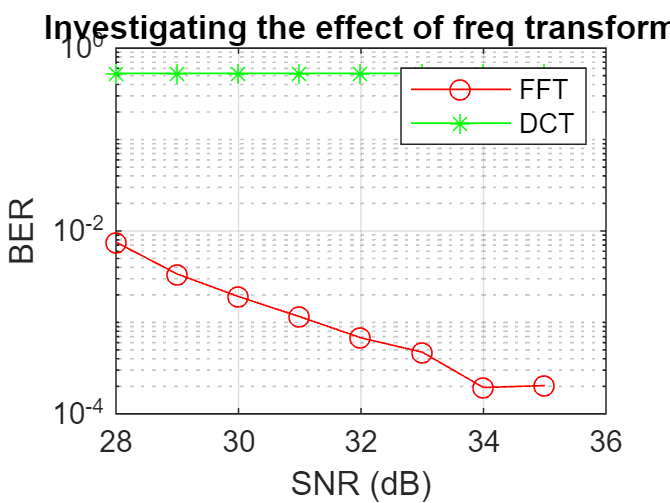

L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Float';
equalization_method = 'Weiner';

setPreamble("Default"); setCoding('CONV');
SNR_DB_Arr = 28:35;

setTransform("DCT");
BER_Vals_dct = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_dct = [BER_Vals_dct ratio];
end

setTransform("FFT");
BER_Vals_fft = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_fft = [BER_Vals_fft ratio];
end

figure();
semilogy(SNR_DB_Arr, BER_Vals_fft,'r-o', ...
    SNR_DB_Arr, BER_Vals_dct,'g-*');
title('Investigating the effect of freq transform');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('FFT', 'DCT');

## c. Investigating the effect of the transform techniques (performance)

L = 1000;R = 54;codeRate = 3/4;modulation_type = '64QAM';rep_type = 'Float';
equalization_method = 'Weiner';

setPreamble("Default"); setCoding('CONV');
setTransform("FFT");
% ====== FFT ========
disp("For FFT:-")

For FFT:-


tic
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
toc

Elapsed time is 1.886757 seconds.


output_fileID = fopen('Output/test2_fft.txt','w');
fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

% ====== DCT ========
setTransform("DCT");
disp("For DCT:-")

For DCT:-


tic
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
toc

Elapsed time is 3.578084 seconds.


output_fileID = fopen('Output/test2_dct.txt','w');
fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

## d. Comparison between the BER performance of the ZF equalizer and the Weiner equalizer. 

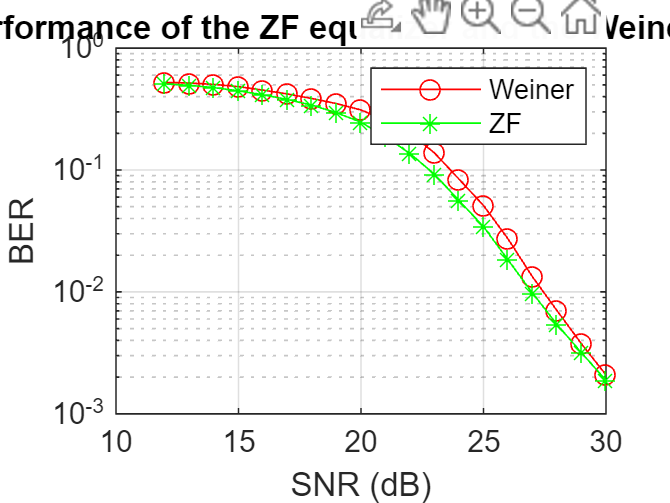

L = 1000;R = 54;codeRate = 3/4;modulation_type = '64QAM';rep_type = 'Float';
SNR_DB_Arr = 12:30;

setPreamble("Default"); setCoding('CONV');
setTransform("FFT");
BER_Vals_wf = [];
BER_Vals_zf = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    % Receiver
    [decoded_data_wf, ~, ~] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
    [decoded_data_zf, ~, ~] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);
    [~, ratio_wf] = biterr(decoded_data_wf',data);
    [~, ratio_zf] = biterr(decoded_data_zf',data);
    BER_Vals_wf = [BER_Vals_wf ratio_wf];
    BER_Vals_zf = [BER_Vals_zf ratio_zf];
end
figure();
semilogy(SNR_DB_Arr, BER_Vals_wf,'r-o', ...
    SNR_DB_Arr, BER_Vals_zf,'g-*');
title('BER performance of the ZF equalizer and the Weiner equalizer');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Weiner', 'ZF');

## e. Constellation diagram of the received symbols after equalization using the ZF equalizer, and the Weiner equalizer at any SNR of your choice (one figure for each equalizer).

#### SNR = 10

setPreamble("");setTransform("FFT");
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Float';

snr = 10;
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr);
% Receiver
[~, ~, eq_frames_w] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
[~, ~, eq_frames_zf] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);

scatterplot(eq_frames_w);
title('Constellation diagram after Weiner Equalizer (SNR = 10)');
scatterplot(eq_frames_zf);
title('Constellation diagram after ZF Equalizer (SNR = 10)');

#### SNR = 30

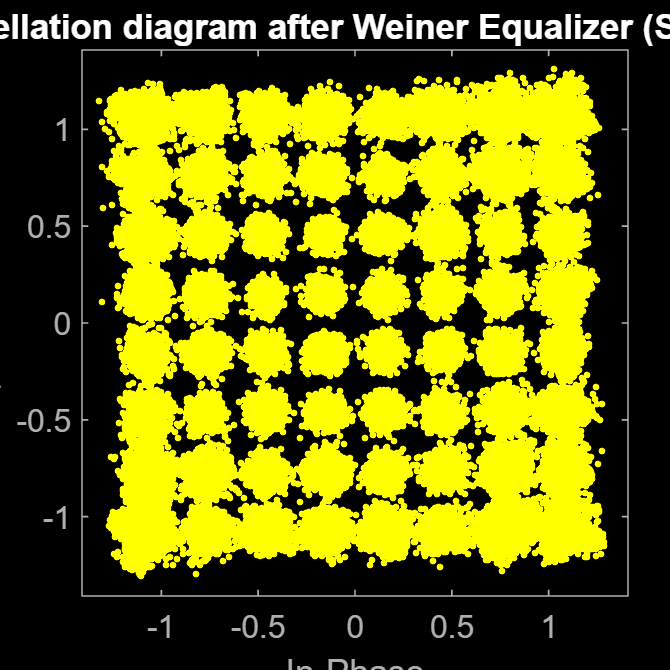

snr = 30;
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr);
% Receiver
[~, ~, eq_frames_w] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
[~, ~, eq_frames_zf] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);

scatterplot(eq_frames_w);
title('Constellation diagram after Weiner Equalizer (SNR = 30)');

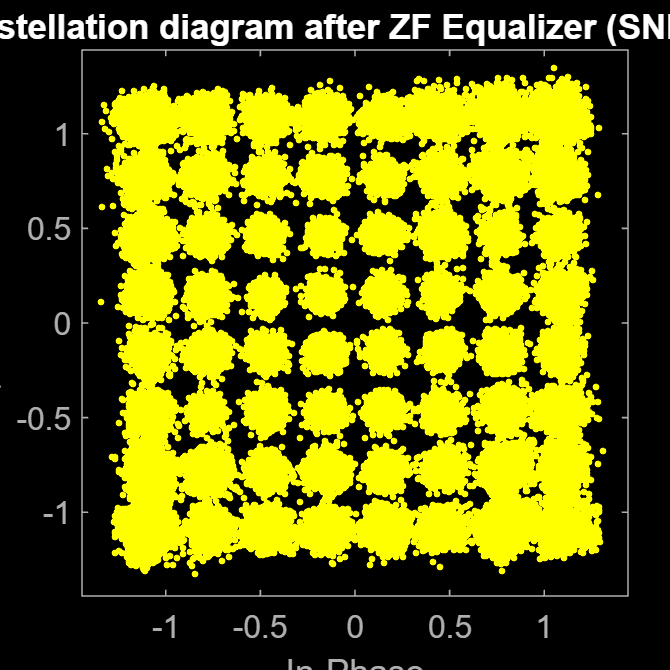

scatterplot(eq_frames_zf);
title('Constellation diagram after ZF Equalizer (SNR = 30)');

## f. Comparison between the BER performance of all standard supported rates using the floating point implementation (all curves on the same figure).

L = 1000;
setPreamble("Default"); setTransform("FFT"); setCoding("CONV");
SNR_DB_Arr = 12:30;

RArr6 = [];
RArr9 = [];
RArr12 = [];
RArr18 = [];
RArr24 = [];
RArr36 = [];
RArr48 = [];
RArr54 = [];
for snr = SNR_DB_Arr
    % R = 6
    ber_6 = apply_no_save(data, L, 6, 1/2,'BPSK', 'Float', snr, 'Weiner');
    RArr6 = [RArr6 ber_6];
    % R = 9
    ber_9 = apply_no_save(data, L, 9, 3/4,'BPSK', 'Float', snr, 'Weiner');
    RArr9 = [RArr9 ber_9];
    % R = 12
    ber_12 = apply_no_save(data, L, 12, 1/2,'QPSK', 'Float', snr, 'Weiner');
    RArr12 = [RArr12 ber_12];
    % R = 18
    ber_18 = apply_no_save(data, L, 18, 3/4,'QPSK', 'Float', snr, 'Weiner');
    RArr18 = [RArr18 ber_18];
    % R = 24
    ber_24 = apply_no_save(data, L, 24, 1/2,'16QAM', 'Float', snr, 'Weiner');
    RArr24 = [RArr24 ber_24];
    % R = 36
    ber_36 = apply_no_save(data, L, 36, 3/4,'16QAM', 'Float', snr, 'Weiner');
    RArr36 = [RArr36 ber_36];
    % R = 48
    ber_48 = apply_no_save(data, L, 48, 2/3,'64QAM', 'Float', snr, 'Weiner');
    RArr48 = [RArr48 ber_48];
    % R = 54
    ber_54 = apply_no_save(data, L, 54, 3/4,'64QAM', 'Float', snr, 'Weiner');
    RArr54 = [RArr54 ber_54];
end

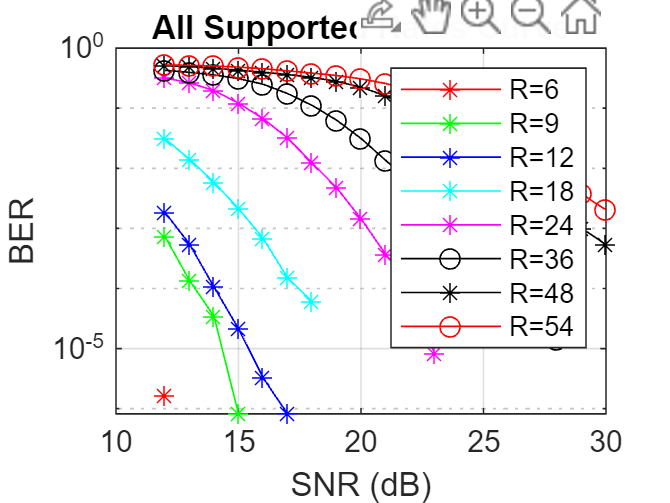

figure();
semilogy(SNR_DB_Arr, RArr6,'r-*', ...
    SNR_DB_Arr, RArr9,'g-*',...
    SNR_DB_Arr, RArr12,'b-*',...
    SNR_DB_Arr, RArr18,'c-*',...
    SNR_DB_Arr, RArr24,'m-*',...
    SNR_DB_Arr, RArr36,'k-o',...
    SNR_DB_Arr, RArr48,'k-*',...
    SNR_DB_Arr, RArr54,'r-o');
title('All Supported Rates Curve');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('R=6', ...
    'R=9',...
    'R=12',...
    'R=18',...
    'R=24',...
    'R=36',...
    'R=48',...
    'R=54');

## g. Comparison between the BER performance of different channel coding techniques for the  64QAM modulation using the floating-point implementation (all curves on the same figure)

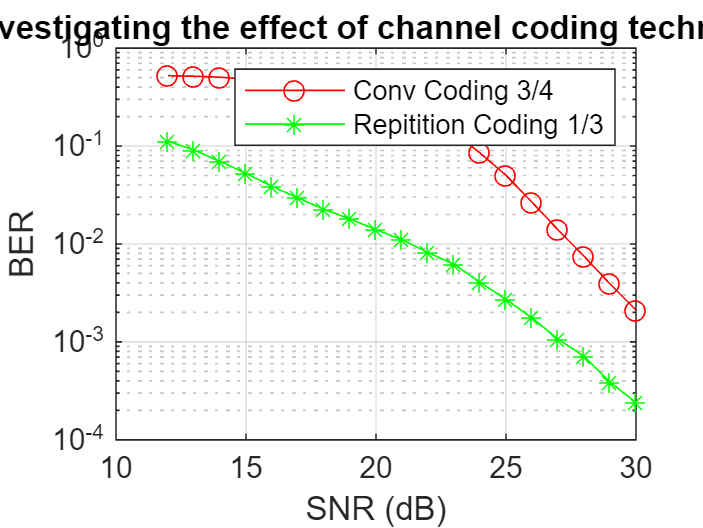

SNR_DB_Arr = 12:30;
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Float';
equalization_method = 'Weiner';

setPreamble("");setTransform("FFT");
setCoding("CONV");
BER_Vals_conv = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_conv = [BER_Vals_conv ratio];
end
setCoding("REP");
BER_Vals_repition = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_repition = [BER_Vals_repition ratio];
end

% setCoding("LDPC");
% BER_Vals_LDPC = [];
% for snr = SNR_DB_Arr
%     % Transmitter
%     transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
%     % Channel
%     rxed_frames = apply_channel(transmitted_frames, snr);
%     % Receiver
%     equalization_method = 'Weiner';
%     [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
%     [BER, ratio] = biterr(decoded_data',data);
%     BER_Vals_LDPC = [BER_Vals_LDPC ratio];
% end
figure();
semilogy(SNR_DB_Arr, BER_Vals_conv,'r-o', ...
    SNR_DB_Arr, BER_Vals_repition,'g-*');
title('Investigating the effect of channel coding technique');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Conv Coding 3/4', 'Repitition Coding 1/3');

## h. Comparison between the BER performance of the floating-point and fixed-point implementations for 16QAM modulation, and 3/4 code rate (both curves on the same figure).

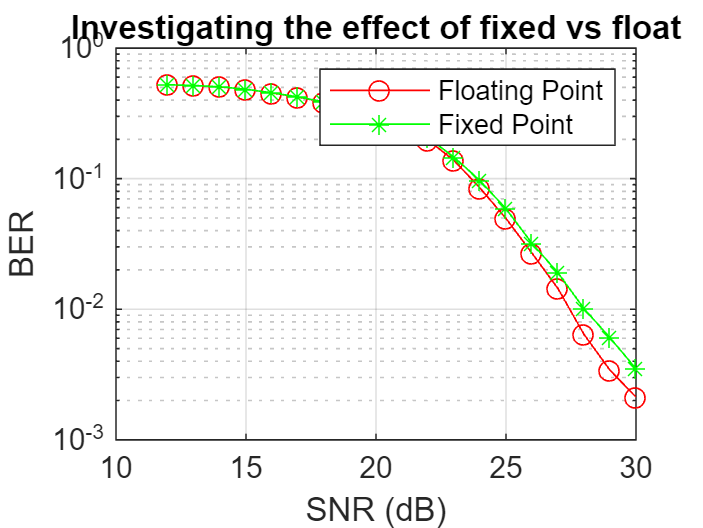

SNR_DB_Arr = 12:30;
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
equalization_method = 'Weiner';

setPreamble("");setTransform("FFT");
setCoding("CONV");

rep_type = 'Fixed';
BER_Vals_fixed = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr, true);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_fixed = [BER_Vals_fixed ratio];
end
rep_type = 'Float';
BER_Vals_float = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_float = [BER_Vals_float ratio];
end

figure();
semilogy(SNR_DB_Arr, BER_Vals_float,'r-o', ...
    SNR_DB_Arr, BER_Vals_fixed,'g-*');
title('Investigating the effect of fixed vs float');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Floating Point', 'Fixed Point');

## i. Repeat part e using the fixed-point implementation

#### SNR = 10

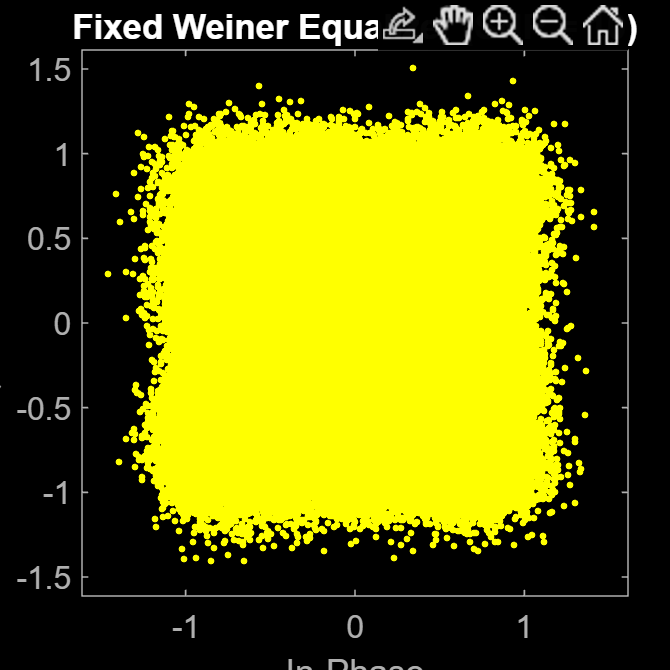

setPreamble("");setTransform("FFT");
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Fixed';

snr = 10;
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr, true);
% Receiver
[~, ~, eq_frames_w] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
[~, ~, eq_frames_zf] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);
scatterplot(eq_frames_w.data);
title('Fixed Weiner Equalizer (SNR = 10)');

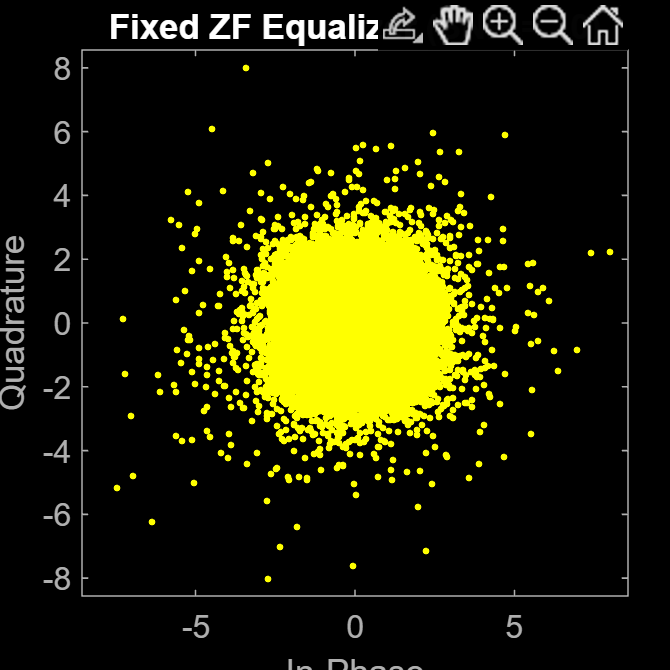

scatterplot(eq_frames_zf.data);
title('Fixed ZF Equalizer (SNR = 10)');

#### SNR = 30

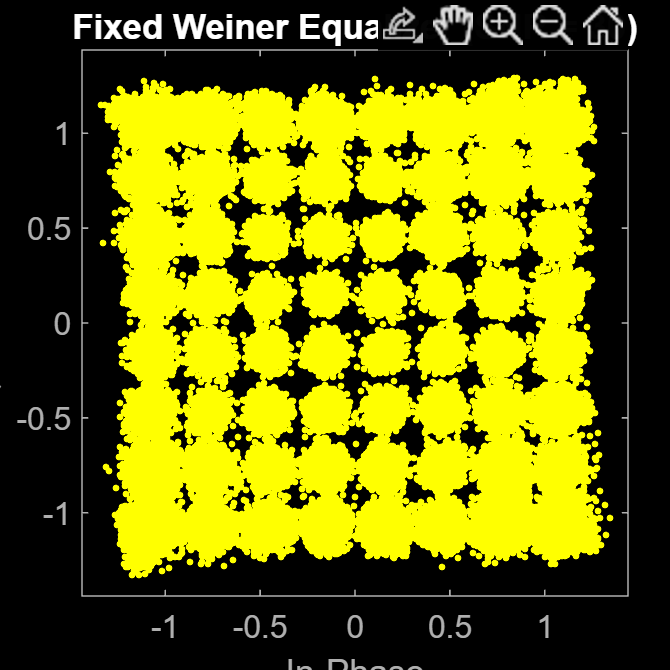

snr = 30;
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, snr,true);
% Receiver
[~, ~, eq_frames_w] = Wifi_Receiver(rxed_frames, "Weiner", rep_type, snr);
[~, ~, eq_frames_zf] = Wifi_Receiver(rxed_frames, "ZF", rep_type, snr);

scatterplot(eq_frames_w.data);
title('Fixed Weiner Equalizer (SNR = 30)');

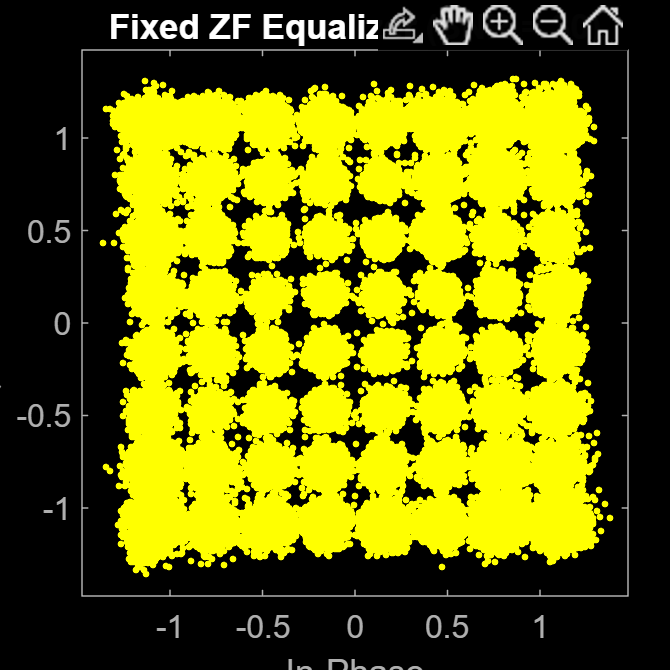

scatterplot(eq_frames_zf.data);
title('Fixed ZF Equalizer (SNR = 30)');